clear all;
clc;

% Iciación de arduino y full scale con el aref interno de la placa (1.1 volts).

a = arduino('COM3','Uno','AnalogReferenceMode','internal','AnalogReference',1.1)

a =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {}
Show all properties



volt = 'A0'; % Declaración de la variable volt asociada al puerto analógico
             % cero de arduino.

t = 0;

j = 1;

tStart = tic; % Registro de tiempo para el ciclo for

for j = 1:1:90 % Se pueden modificar las iteraciones para ajustar el tiempo
                 % Teniendo en cuenta que cada iteración equivale a cinco
                 % segundos.
    sensor = readVoltage(a,volt); % Leer el puerto analógico 0 de arduino.
    Volt = sensor * 1000; % Convertir la señal de voltios a milivoltios.
    Temp = Volt / 10; %Convertir voltaje a tempreratura.
    disp(Volt); fprintf('mV \n'); % Mostrar el valor sensado.
    disp(Temp); fprintf('°C \n'); % Motrar valor de temperatura.
    data_volt(j) = Volt; % Escritura de los datos de voltaje en un vector.
    data_temp(j) = Temp; % Escritura de los datos temperatura en un vector.
    Iteraciones(j) = t; % Escritura del tiempo en un vector.
    t = t + 1;
end

  189.2473

mV 


   18.9247

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  213.9785

mV 


   21.3978

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  212.9032

mV 


   21.2903

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  212.9032

mV 


   21.2903

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  212.9032

mV 


   21.2903

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  216.1290

mV 


   21.6129

°C 


  213.9785

mV 


   21.3978

°C 


  213.9785

mV 


   21.3978

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  216.1290

mV 


   21.6129

°C 


  216.1290

mV 


   21.6129

°C 


  213.9785

mV 


   21.3978

°C 


  213.9785

mV 


   21.3978

°C 


  216.1290

mV 


   21.6129

°C 


  216.1290

mV 


   21.6129

°C 


  216.1290

mV 


   21.6129

°C 


  215.0538

mV 


   21.5054

°C 


  215.0538

mV 


   21.5054

°C 


  213.9785

mV 


   21.3978

°C 


  215.0538

mV 


   21.5054

°C 



tEnd = toc(tStart); % Finaliza registro de tiempo ciclo for y se guarda en tEnd.

frec_muest = length(data_temp) / tEnd; % Cálculo de frecuencia de muestreo.

mov_avg_temp = movavg(transpose(data_temp),'linear',10); % Cálclo de la media móvil cada diez datos.

Tiempo = Iteraciones ./ frec_muest;

% Creación de tabla con los datos de tiempo, voltaje, temperatura y media móvil de la temperatura.
T = table(Tiempo',data_volt',data_temp',mov_avg_temp,'VariableNames', ...
    {'Tiempo [s]','Volataje [mv]','Temperatura [°C]','Media Móvil Temperatura [°C]'})

T = 90×4 table
    Tiempo [s]    Volataje [mv]    Temperatura [°C]    Media Móvil Temperatura [°C]
    __________    _____________    ________________    ____________________________

            0        189.25             18.925                    18.925           
     0.056281        215.05             21.505                    20.283           
      0.11256        215.05             21.505                    20.741           
      0.16884        216.13             21.613                    21.006           
      0.22512        215.05             21.505                    21.142           
       0.2814        213.98             21.398                    21.214           
      0.33768        215.05             21.505                     21.29           
      0.39396        213.98             21.398                    21.332           
      0.

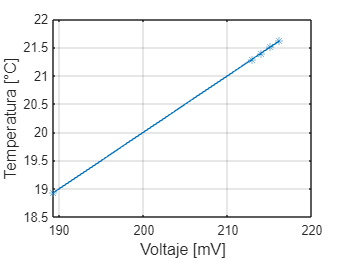


filename = 'Caract_LM35.xlsx';

writetable(T,filename);

plot(data_volt,data_temp,'*-')

xlabel('Voltaje [mV]','FontSize',12)

ylabel('Temperatura [°C]','FontSize',12)

grid on

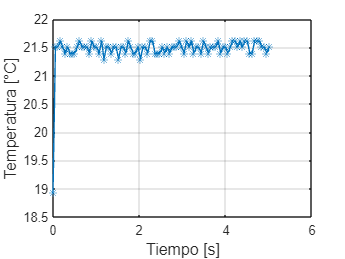


plot(Tiempo,data_temp,'*-')

xlabel('Tiempo [s]','FontSize',12)

ylabel('Temperatura [°C]','FontSize',12)

grid on

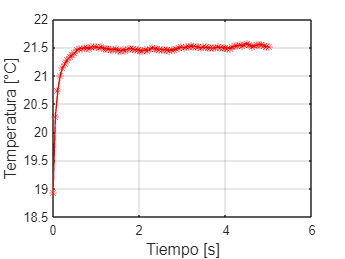


plot(Tiempo,mov_avg_temp','r*-')

xlabel('Tiempo [s]','FontSize',12)

ylabel('Temperatura [°C]','FontSize',12)

grid on


% Cálculo de la frecuencia más alta de la señal.

Fourier = fft(mov_avg_temp);

Norm_espec = abs(Fourier) / length(Fourier);

[~, index_max] = max(Norm_espec);

% Frecuencia más alta de la señal.

F_max = index_max * frec_muest / length(Fourier)

F_max = 0.1974



if frec_muest >= (2*F_max)
    fprintf('Sí cumple con el Toerema de Nyquist')
end

Sí cumple con el Toerema de Nyquist